# Continuation of periodic orbits

We compute a family of periodic orbits emanating from a Hopf bifurcation point of the dynamical system (see Recipes for continuation Example 8.3 for more details)


$$\dot{x}_1 = p_1x_1 + x_2 + p_2x_1^2,\\
\dot{x}_2 = -x_1 + p_1x_2 + x_2x_3,\\
\dot{x}_3 = (p_1^2 - 1)x_2 - x_1 - x_3 + x_1^2
$$


The equilibrium $x=0$ undergoes a Hopf bifurcation as $p_1$ crosses $p_1^\ast=0$ for arbitrary $p_2$.

## Construct an of initial periodic orbit 

clear all
p0 = [0.0; 6];
T0 = 0;
T  = 2*pi;
x0 = 0.01*[1 0 -1]'; % from Hopf normal form (see Recipes for continuation Example 8.3 for more details)
x1 = x0;

## Continuation of periodic orbit

prob = coco_prob();
% argument
forward_args = {@marsden, @marsden_dx, @marsden_dp, T0, T, x0, x1, {'p1' 'p2'}, p0};
prob1 = ode_isol2forward(prob, '',forward_args{:});
% add boundary conditions (periodic conditions + a phase condition)
[data, uidx] = coco_get_func_data(prob1, 'forward', 'data', 'uidx');
bc_funcs = {@marsden_bc, @marsden_bc_du};
prob1 = coco_add_func(prob1, 'bc', bc_funcs{:}, [], 'zero', 'uidx', ...
  uidx([data.x0_idx, data.x1_idx, data.T0_idx]));
% monitor period of periodic orbits 
prob1 = coco_add_pars(prob1, '', uidx(data.T_idx), 'T');

% continuation
cont_pars = {'p1' 'T' 'p2'};
coco(prob1, 'marsden-isol', [], 1, cont_pars, [-2 0]);

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          4.00e-04  1.07e+01    0.0    0.0    0.0
   1   1  1.00e+00  4.72e-03  1.03e-05  1.07e+01    0.0    0.0    0.0
   2   1  1.00e+00  9.62e-04  5.23e-07  1.07e+01    0.1    0.0    0.0
   3   1  1.00e+00  4.79e-05  1.69e-09  1.07e+01    0.1    0.0    0.0
   4   1  1.00e+00  1.18e-07  7.02e-10  1.07e+01    0.1    0.0    0.0

 STEP      TIME        ||U||  LABEL  TYPE            p1            T           p2
    0  00:00:00   1.0725e+01      1  EP     -1.0418e-04   6.2861e+00   6.0000e+00
   10  00:00:00   1.0872e+01      2         -4.2593e-03   6.4104e+00   6.0000e+00
   17  00:00:01   1.2480e+01      3  FP     -2.0251e-02   7.7366e+00   6.0000e+00
   20  00:00:01   1.3276e+01      4         -1.9042e-02   8.3731e+00   6.0000e+00
   23  00:00:02   1.3549e+01      5  MX     -1.8375e-02   8.5892e+00   6.0000e+00

 STEP      TIME 

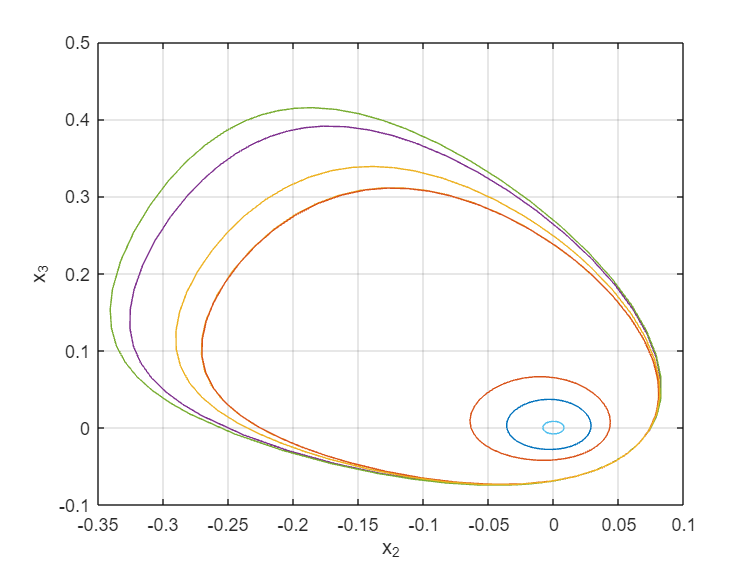

% plot of periodic orbits
figure; hold on
for lab = 1:10
    sol = forward_read_solution('', 'marsden-isol', lab);
    odefun = @(t,x) marsden(x,sol.p);
    [~,x] = ode45(odefun,[0,sol.T],sol.x0);
    plot(x(:,2),x(:,3))
end
grid on; box on
xlabel('x_2'); ylabel('x_3')